# 1.3.08 Символьная алгебра

**Практическое занятие**

Периодическая функция с периодом T=2L может быть разложена в тригонометрический ряд Фурье вида:


$$f\left(x\right)=\frac{a_0 }{2}+\sum_{k=1}^{\infty } \left(a_k \cdot \mathrm{cos}\left(\frac{\pi kx}{L}\right)+b_k \cdot \mathrm{sin}\left(\frac{\pi kx}{L}\right)\right),$$


где $a_0$, $a_k$и $b_k$ являеются коэффициентами Фурье, и определяются по формулам Эйлера-Фурье:


$$\begin{cases} 
a_k =\frac{1}{L}\int_{-L}^L f\left(x\right)\mathrm{cos}\left(\frac{\pi kx}{L}\right)\mathrm{dx},k=0,1,2\;\ldotp \ldotp \ldotp \ldotp, \\
b_k =\frac{1}{L}\int_{-L}^L f\left(x\right)\mathrm{sin}\left(\frac{\pi kx}{L}\right)\textrm{dx},k=0,1,2\;\ldotp \ldotp \ldotp \ldotp. 
\end{cases}$$


Для заданной функции$f\left(x\right)$ найдите коэффициенты Фурье в аналитическом виде, разложите функцию в ряды Фурье с различным количеством членов ряда: 3, 5, 7, 50. Постройте график функции $f\left(x\right)$ и ее разложений в ряд Фурье с различным числом членов ряда. Функция $f\left(x\right)$-периодическая, и представляет собой меандр с периодом $T=2\pi$, на отрезке $\left.\lbrack -\pi ,\pi \right)$ описывается следующим выражением:


$$f\left(x\right)=\left\lbrace \begin{array}{ccc}
1 & \textrm{if}\; & x\in \left\lbrack -\pi ,\;0\right)\\
0 & \textrm{if} & \;x\in \left\lbrack 0,\pi \right)
\end{array}\right.$$


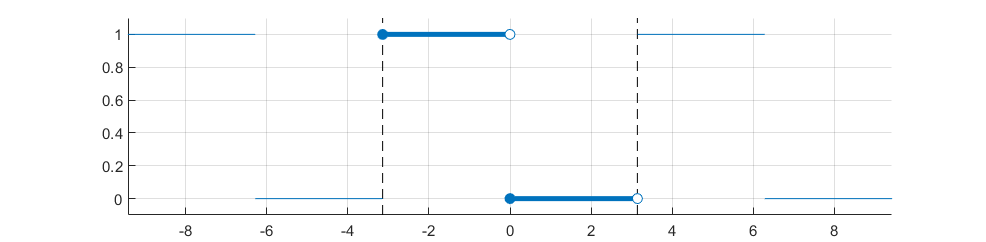

#### 1. Создайте символьные переменные:

 $x$- независимая переменная, $k$- количество членов ряда.

syms x k

#### 2. Задайте кусочно-линейную функцию $f\left(x\right)$

Воспользуйтесь командой `piecewise()`, проверить правильность задания функции можно построив ее график командой `fplot()`

f_x=piecewise(-pi<=x<0,1,0<=x<=pi,0)

$$f\_x = \left\{ \begin{array}{cl} 1 & \text{ if }x\in \left[-\pi ,0\right)\\ 0 & \text{ if }x\in \left[0,\pi \right] \end{array}\right.$$

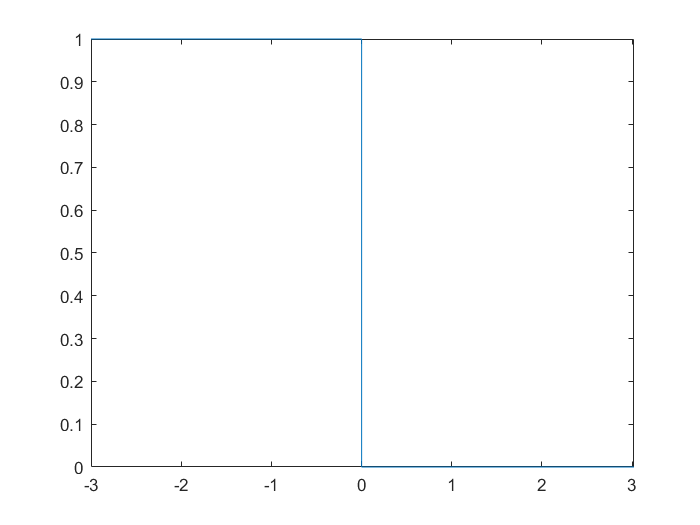

fplot(f_x)

#### 3. Вычислите коэффициенты Фурье

% Задайте период функции T
T=2*pi;
% Вычислите полупериод L
L=T/2

$$L = \pi$$

% Найдите a_0, a_k, b_k
a_0=1/L*int(f_x,x,-pi,pi)

$$a\_0 = 1$$

a_k=1/L*int(f_x*cos(k*x*pi/L),x,-pi,pi)

$$a\_k = \frac{\sin\left(\pi \,k\right)}{k\,\pi }$$

b_k=1/L*int(f_x*sin(k*x*pi/L),x,-pi,pi)

$$b\_k = \frac{\cos\left(\pi \,k\right)-1}{k\,\pi }$$

#### 4. Разложите функцию в ряды Фурье с количеством членов ряда 3, 5, 7, 50

sum3 = a_0/2 + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,3)

$$sum3 = \frac{1}{2}-\frac{2\,\sin\left(x\right)}{\pi }-\frac{2\,\sin\left(3\,x\right)}{3\,\pi }$$

sum5 = a_0/2 + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,5)

$$sum5 = \frac{1}{2}-\frac{2\,\sin\left(5\,x\right)}{5\,\pi }-\frac{2\,\sin\left(x\right)}{\pi }-\frac{2\,\sin\left(3\,x\right)}{3\,\pi }$$

sum7 = a_0/2 + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,7)

$$sum7 = \frac{1}{2}-\frac{2\,\sin\left(5\,x\right)}{5\,\pi }-\frac{2\,\sin\left(7\,x\right)}{7\,\pi }-\frac{2\,\sin\left(x\right)}{\pi }-\frac{2\,\sin\left(3\,x\right)}{3\,\pi }$$

sum50 = a_0/2 + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,50)

$$sum50 = \frac{1}{2}-\frac{2\,\sin\left(5\,x\right)}{5\,\pi }-\frac{2\,\sin\left(7\,x\right)}{7\,\pi }-\frac{2\,\sin\left(9\,x\right)}{9\,\pi }-\frac{2\,\sin\left(11\,x\right)}{11\,\pi }-\frac{2\,\sin\left(13\,x\right)}{13\,\pi }-\frac{2\,\sin\left(15\,x\right)}{15\,\pi }-\frac{2\,\sin\left(17\,x\right)}{17\,\pi }-\frac{2\,\sin\left(19\,x\right)}{19\,\pi }-\frac{2\,\sin\left(21\,x\right)}{21\,\pi }-\frac{2\,\sin\left(23\,x\right)}{23\,\pi }-\frac{2\,\sin\left(25\,x\right)}{25\,\pi }-\frac{2\,\sin\left(27\,x\right)}{27\,\pi }-\frac{2\,\sin\left(29\,x\right)}{29\,\pi }-\frac{2\,\sin\left(31\,x\right)}{31\,\pi }-\frac{2\,\sin\left(33\,x\right)}{33\,\pi }-\frac{2\,\sin\left(35\,x\right)}{35\,\pi }-\frac{2\,\sin\left(37\,x\right)}{37\,\pi }-\frac{2\,\sin\left(39\,x\right)}{39\,\pi }-\frac{2\,\sin\left(41\,x\right)}{41\,\pi }-\frac{2\,\sin\left(43\,x\right)}{43\,\pi }-\frac{2\,\sin\left(45\,x\right)}{45\,\pi }-\frac{2\,\sin\left(47\,x\right)}{47\,\pi }-\frac{2\,\sin\left(49\,x\right)}{49\,\pi }-\frac{2\,\sin\left(x\right)}{\pi }-\frac{2\,\sin\left(3\,x\right)}{3\,\pi }$$

#### 5. Упростите выражения, хранящиеся в переменных sum3, sum5, sum7 с помощью функции simplify()

sum3 = simplify(sum3)

$$sum3 = \frac{16\,{\sin\left(x\right)}^{3}-24\,\sin\left(x\right)+3\,\pi }{6\,\pi }$$

simplify(sum5)

$$ans = \frac{-192\,{\sin\left(x\right)}^{5}+320\,{\sin\left(x\right)}^{3}-180\,\sin\left(x\right)+15\,\pi }{30\,\pi }$$

simplify(sum7)

$$ans = \frac{3840\,{\sin\left(x\right)}^{7}-8064\,{\sin\left(x\right)}^{5}+5600\,{\sin\left(x\right)}^{3}-1680\,\sin\left(x\right)+105\,\pi }{210\,\pi }$$

#### 6. Постройте на одних осях график функции $f\left(x\right)$ и полученные разложения в ряд.

fplot(sum3),grid, hold,

Current plot held


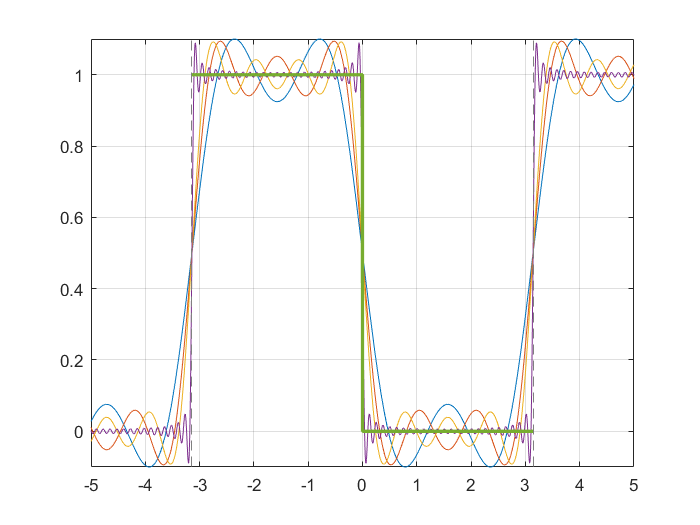

fplot(sum5)
fplot(sum7)
fplot(sum50)
fplot(f_x,'LineWidth',2)